# **RAGA DETECTOR**

# DATABASE

name=["kanakangi","ratnangi","ganamoorti","vanaspati","manavati","tanaroopi","senavati","hanumatodi","dhenuka","natakapriya","kokilapriya","rupavati","gayakapriya","vakulabharanam","mayamalava gowla","chakravakam","sooryakantam","hatakambari","jhankaradhvani","natabhairavi","keeravani","kharaharapriya","gowri manohari","varunapriyaa","mararanjani","charukeshi","sarasangi","harikambhoji","dheera shankarabharanam","naganandhini"];
values=[3164,3162,3161,3158,3157,3155,3420,3418,3417,3414,3413,3411,3292,3290,3289,3286,3285,3283,2908,2906,2905,2902,2901,2899,2780,2778,2777,2774,2773,2771];

# Sample pitch naming 

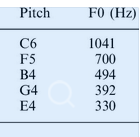

A=440 Hz standard

y=pitchname(70.31)

y = "C#4"

# Record the audio, and play

fs=44100;
[song1,fs]=audioread('harmonicminor.wav');
sound(song1,fs);
song1;

# Run the module function and find the musical notes

rag=raga(song1,fs);


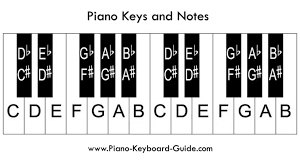

Notation=["A","A#","B","C","C#","D","D#","E","F","F#","G","G#","A";"S","R1","R2","G2/R3","G3","M1","M2","P","D1","D2/N1","N2/D3","N3","S"];
rag

rag =     0.9529         0    0.4941    0.5882         0    0.5294    0.0235    0.6118    1.0000    0.0118         0    0.6118         0


scale=Notation(:,rag>0.2)

scale = 2×7 string array
    "A"    "B"     "C"        "D"     "E"    "F"     "G#"
    "S"    "R2"    "G2/R3"    "M1"    "P"    "D1"    "N3"


# Searching the database using binary weights

s=0;
for i=1:12
    if rag(i)>.2
        s=s+2^(12-i);
    end
end
s

s = 2905

result=0;
for i=1:30
    if values(i)==s
        result=name(i);
    end
end
result

result = "keeravani"

#   ***f***** =440•2^(***n* /12)

function [y,n]=pitchname(x)
    Notation=["A","A#","B","C","C#","D","D#","E","F","F#","G","G#","A"];
    n=log2(x/440)*12;
    n=round(abs(mod(n,12)))+1;
    y=Notation(n)+join(string(floor(x/440)+4));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y=raga(song,fs)
tmp=[0,0,0,0,0,0,0,0,0,0,0,0,0];
song=transpose(song);
for i=(1:1024:length(song)-4196)
    k=song(i:i+1024);
    f=freqcorr(k,fs);
    [m,n]=pitchname(f);
    m;
    tmp(n)=tmp(n)+1;
end
y=tmp;
y=y/max(y);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function f=freqcorr(song,fs)
temp=xcorr(song);
    [p0,t]=findpeaks(temp);
    [m,peaks]=max(p0);
    f=fs/(t(peaks+1)-t(peaks));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function x=record(fs)
    beep2();
    pause(.5);
    x=audiorecorder(fs,8,1);
    
    recordblocking(x,5);
 
    x=getaudiodata(x);
    beep2();
    %x=nonzeros(x);
end
function beep2()
% Play a sine wave
res = 21000;
len = 0.5 * res;
hz = 220;
sound( sin( hz*(2*pi*(0:len)/res) ), res);
end

